# Homework 5

## Problem 1

Let’s assume that we have performed a 20-point DFT on a sequence of real-valued time-domain samples, and we want to send our X(m) DFT results to a colleague using e-mail. What is the absolute minimum number of (complex) frequency-domain sample values we will need to type in our e-mail so that our colleague has complete information regarding our DFT results?

**Answer:**

A 20 point DFT creats 20 different compolex numbers so you will need to send all 20 numbers to get the complete information.

## Problem 2

Assume a systems engineer directs you to start designing a system that performs spectrum analysis using DFTs. The systems engineer states that the spectrum analysis system’s input data sample rate, fs , is 1000 Hz and specifies that the DFT’s frequency-domain sample spacing must be exactly 45 Hz. 

(a) What is the number of necessary input time samples, N, for a single DFT operation? 

(b) What do you tell the systems engineer regarding the spectrum analysis system’s specifications? 

**Answer:**

A) The number of nessesary samples N for a single DFT operation is 22

B) You can tell the system engineer that regarding the spectrum analyis system's specification that the signal has a fundamental frequency of 45Hz and the sampling frequency of the signal is 1000Hz.

## Problem 3

We want to compute an N-point DFT of a one-second-duration compact disc (CD) audio signal x(n), whose sample rate is fs = 44.1 kHz, with a DFT sample spacing of 1 Hz.

 (a) What is the number of necessary x(n) time samples, N? 

(b) What is the time duration of the x(n) sequence measured in seconds?

**Answer:**

A) The number of necessary time sample is 44100

B) The time duration of the sequence measured is 22.6*10^6

## Problem 4

Assume we have a discrete x(n) time-domain sequence of samples obtained from lowpass sampling of an analog signal, x(t). If x(n) contains N = 500 samples, and it was obtained at a sample rate of fs = 3000 Hz:

 (a) What is the frequency spacing of x(n)’s DFT samples, X(m), measured in Hz? 

(b) What is the highest-frequency spectral component that can be present in the analog x(t) signal where no aliasing errors occur in x(n)? 

c) If you drew the full X(m) spectrum and several of its spectral replications, what is the spacing between the spectral replications measured in Hz?

**Answer:**

A) The frequency spacing of the DFT samples are 6Hz

B) The highest frequency spectral component is 1500Hz

C) The spacing betweent eh spectral replications is 1500 Hz

## Problem 5

What are the magnitudes of the 8-point DFT samples of 

(a) the x1 (n) = 9, 9, 9, 9, 9, 9, 9, 9 sequence (explain how you arrived at your solution)?

 (b) the x2 (n) = 1, 0, 0, 0, 0, 0, 0, 0 sequence? 

(c) the x3 (n) = 0, 1, 0, 0, 0, 0, 0, 0 sequence? 

Because the x3 (n) sequence in Part (c) is merely a time-shifted version of the x2 (n) sequence in Part (b), comment on the relationship of the |X2 (m)| and |X3 (m)| DFT samples. 

**Answer:**

A) The magnitude is 72 because the imaginary part would cancel out so you could just add up the integer values.

B) The magnitude is 1

C) The magnitude is 1

x2 and x3 since it is just time shifted the magnitude is the same for both and the |X2 (m)| and |X3 (m)|  DFT samples are th same but shifted

## Problem 6

Consider sampling exactly three cycles of a continuous x(t) sinusoid resulting in an 8-point x(n) time sequence whose 8-point DFT is the X(m) shown in Figure P3-6. If the sample rate used to obtain x(n) was 4000 Hz, write the time-domain equation for the discrete x(n) sinusoid in trigonometric form. Show how you arrived at your answer.

**Answer:**


$$y\left(n\right)=\sum_{k=-\infty }^n x\left(k\right)$$



$$y\left(n\right)-y\left(n-1\right)=x\left(n\right)$$


so $Y\left(z\right)-Y\left(z\right)z^{-1} =X\left(z\right)$


$$Y\left(z\right)=\frac{X\left(z\right)}{1-z^{-1} }$$


## Problem 7

In the text’s Section 3.1 we discussed the computations necessary to compute the X(0) sample of an N-point DFT. That X(0) output sample represents the zero Hz (DC) spectral component of an x(n) input sequence. Because it is the DC component, X(0) is real-only and we’re free to say that an X(0) sample always has zero phase. With that said, here are two interesting DFT problems: 

(a) Given that an N-point DFT’s input sequence x(n) is real-only, and N is an even number, is there any value for m (other than m = 0) for which an X(m) DFT output sample is always real-only?

 (b) Given that N is an odd number, is there any value for m (other than m = 0) where an X(m) DFT output sample is always real-only?

**Answer:**

A) 


$$y\left(n\right)=\sum_{k=-\infty }^n x\left(k\right)$$



$$y\left(n\right)=\sum_{k=-\infty }^n x\left(k\right)u\left(n-k\right)$$



$$y\left(n\right)=x\left(n\right)*u\left(n\right)$$



$$Y\left(z\right)=X\left(z\right)U\left(z\right)$$



$$Y\left(z\right)=\frac{X\left(z\right)}{1-z^{-1} }$$


B)


$$u\left(n\right)*u\left(n\right)=\sum_{k=-\infty }^{\infty } u\left(k\right)u\left(k-1\right)$$



$$u\left(n\right)*u\left(n\right)=\sum_{k=-\infty }^{\infty } u\left(k\right)=\left(n+1\right)u\left(n\right)$$



$$x\left(n\right)=u\left(n\right)*u\left(n\right)$$


so


$$X\left(z\right)=\frac{1}{{\left(1-z^{-1} \right)}^2 },|z|>1$$


## Problem 8

 Using the following rectangular form for the DFT equation:

                                                        
$$X\left(m\right)=\sum_{n=0}^{N-1} x\left(n\right)\left\lbrack \mathrm{cos}\left(2\pi \frac{\mathrm{nm}}{N}\right)-\mathrm{jsin}\left(2\pi \frac{\mathrm{nm}}{N}\right)\right\rbrack$$


(a) Prove that the fs/2 spectral sample is X(N/2) = N · sin(θ) when the x(n) input is a sinusoidal sequence defined by 

                                                                x(n) = sin[2π(fs/2)nts + θ]. 

N is an even number, frequency fs is the x(n) sequence’s sample rate in Hz, time index n = 0, 1, 2, ..., N−1, and θ is an initial phase angle measured in radians. 

Hint: Recall the trigonometric identity sin(α+β) = sin(α)cos(β) + cos(α)sin(β). 

(b) What is X(N/2) when x(n) = sin[2π(fs/2)nts]? 

(c) What is X(N/2) when x(n) = cos[2π(fs/2)nts]? 

**Answer:**

**(a)**

**Correspons to half the sample rate. **

**(b)**

**X(N/2) is fsample/N**

**(c) **

**X(N/2) is 0**

## Problem 9

To gain some practice in using the algebra of discrete signals and the geometric series identities in Appendix B, and to reinforce our understanding of the output magnitude properties of a DFT when its input is an exact integer number of sinusoidal cycles: 

(a) Prove that when a DFT’s input is a complex sinusoid of magnitude Ao (i.e., x(n) = Aoej2πfnts) with exactly three cycles over N samples, the output magnitude of the DFT’s m = 3 bin will be |X(3)| = AoN. Hint: The first step is to redefine x(n)’s f and ts variables in terms of a sample rate fs and N so that x(n) has exactly three cycles over N samples. The redefined x(n) is then applied to the standard DFT equation. 

(b) Prove that when a DFT’s input is a real-only sinewave of peak amplitude Ao (i.e., x(n) = Aosin(2πfnts)) with exactly three cycles over N samples, the output magnitude of the DFT’s m = 3 bin will be |X(3)| = AoN/2. 

Hint: Once you redefine x(n)’s f and ts variables in terms of a sample rate fs and N so that x(n) has exactly three cycles over N samples, you must convert that real sinewave to complex exponential form so that you can evaluate its DFT for m = 3. 

The purpose of this problem is to remind us that DFT output magnitudes are proportional to the size, N, of the DFT. That fact is important in a great many DSP analysis activities and applications. 

**Answers:**

**(a) 3/f = N**$t_s$

    **f**$t_s$ = **3/N**

**    x[n] = **$A_0 e^{2\pi n\frac{3}{n}}$

    **x[k] = **$\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack$$e^{-j\pi \frac{\mathrm{kn}}{N}}$

    **x(n) = **${\sum_{n=0}^{N-1} A}_0 e^{2\pi n\frac{3}{n}}$ * $e^{-j\pi \frac{\mathrm{kn}}{N}}$ =  A$e^{\mathrm{j2}\pi \frac{n}{N}\left(3-k\right)}$

 **   x(3) = A**$e^{j*0}$**=**$\Sigma$** A = NA**

**(b)**

 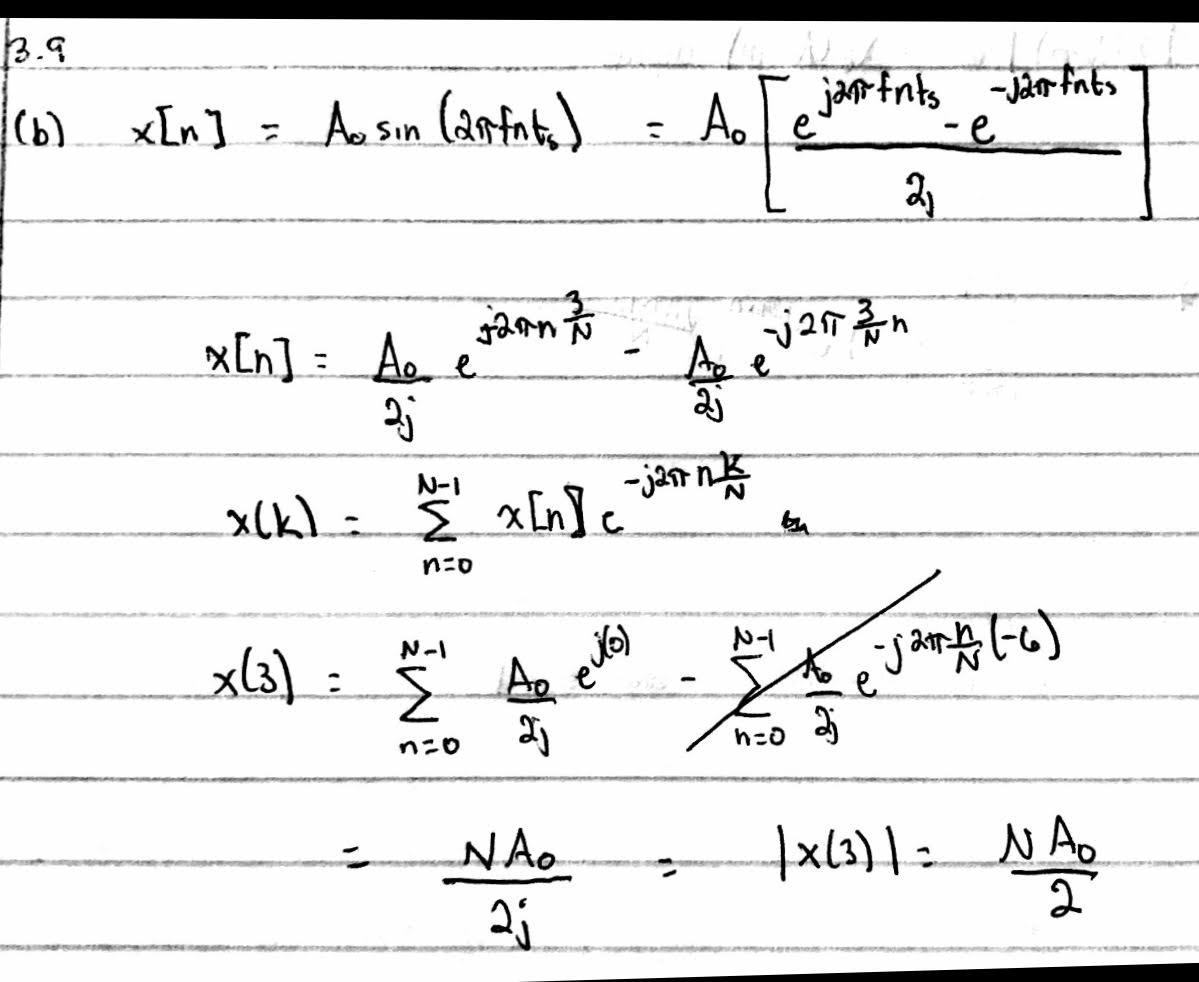

## Problem 10

Consider performing the 5-point DFT on the following x1(n) time-domain samples 

x1(n) = [1, 2.2, −4, 17, 21], 

and the DFT’s first sample is X1(0) = 37.2. Next, consider performing the 5-point DFT on the following x2(n) time samples 

x2(n) = [1, 2.2, −4, 17, Q], 

and that DFT’s first sample is X2(0) = 57.2. What is the value of Q in the x2(n) time sequence? Justify your answer. 

**Answer:**

**Q = 41. Because X(0) is the sum of x(n) samples we can calculate Q by just subtracting X2(0) with x2(n) samples**

x1 = [1, 2.2, -4, 17, 21];
sum(x1)

ans = 37.2000

Q = 57.2 - 1 - 2.2 + 4 - 17

Q = 41

## Problem 11

Derive the equation describing X(m), the N-point DFT of the following x(n) sequence:

 x(n) = a^n,            for 0 ≤ n ≤ N−1.

Hint: Recall one of the laws of exponents, p^bq^(bc) = (pq^c)^b, and the geometric series identities in Appendix B. 

**Answer:**

## Problem 12

Consider an N-sample x(n) time sequence whose DFT is represented by X(m), where 0 ≤ m ≤ N −1. Given this situation, an Internet website once stated, “The sum of the X(m) samples is equal to N times the first x(n) sample.” Being suspicious of anything we read on the Internet, show whether or not that statement is true. 

Hint: Use the inverse DFT process to determine the appropriate x(n) time sample of interest in terms of X(m). 

**Answer:**

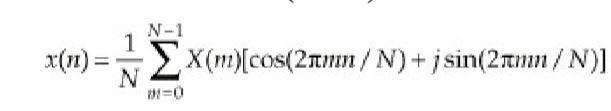

**Using the inverse sample and looking back on of the example problems in the book 3.1.1 and using the results from DFT Example 1 into Eq. (3-23), we’ll go from the frequency domain back to the time domain and get our original real Eq. (3-11′) x(n) sample values of**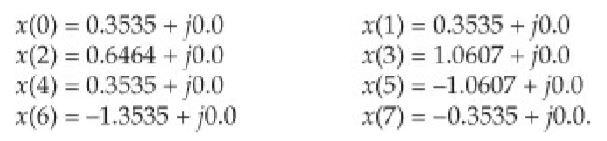

**We already that the sum of these samples is 0 and since N is 8 and the 1st x(n) sample is 0.3535, we now know that this statement is NOT true. **

## Problem 13

Here is a problem whose solution may be useful to you in the future. On the Internet you will find information suggesting that an inverse DFT can be computed using a forward DFT software routine in the process shown in Figure P3-13. 

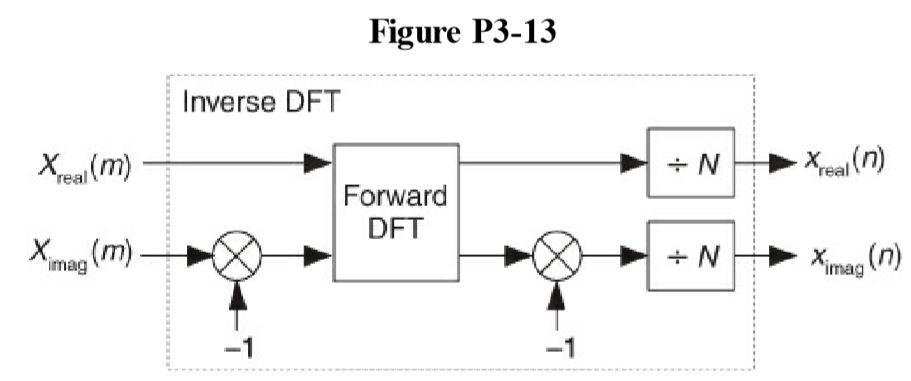

(a) Using the forward and inverse DFT equations, and the material in Appendix A, show why the process in Figure P3-13 computes correct inverse DFTs. Hint: Begin your solution by writing the inverse DFT equation and conjugating both sides of that equation. 

(b) Comment on how the process in Figure P3-13 changes if the original frequency-domain X(m) sequence is conjugate symmetric. 

**Answer:**

**DFT:   **$X\left(k\right)=\sum_{n=0}^{N-1} {x_n e}^{\frac{-\textrm{j2}\pi }{N}\textrm{kn}}$

            
$$x\left(\omega \right)=\sum_{n=-\infty }^{\infty } x\left(n\right)\;e^{-j\omega n}$$


**IDFT: **$X\left(n\right)=\frac{1}{N}\sum_{m=0}^{N-1} {X\left(m\right)e}^{\frac{j\left(2\pi \textrm{nm}\right)}{N}}$

           
$$x\left(n\right)=\frac{1}{N}\;\sum_{k\;=\;0}^{N-1} x\left(k\right)e^{\frac{\left(\textrm{j2}\pi \textrm{nk}\right)}{N}} \;$$


Complex Conjugate:


$$x\left(n\right)\longleftrightarrow x\left(-k*\textrm{mod}\;N\right)$$



$$x\left(-n*\textrm{mod}\;N\right)\longleftrightarrow x\left(k\right)$$


Proven through:

 
$$x\left(k\right)=x\left(-k*\textrm{mod}\;N\right)$$



$$X\left(k\right)=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\textrm{j2}\pi }{N}\left(-k\;\textrm{modN}\right)n}$$


         
$$=\sum_{n=0}^{N-1} {x\left(n\right)e}^{\frac{-\textrm{j2}\pi }{N}\left(\textrm{kn}\right)}$$



$$X\left(-k\;\mathrm{mod}\;N\right)=X\left(k\right)$$


## Problem 14

One useful way to test the performance of commercial analog-to-digital (A/D) converters is to digitize an fo Hz analog sinewave, apply the N-sample x(n) sequence to a DFT, and examine the DFT’s X(m) results. The process is depicted in Figure P3-14. An ideal (A/D) converter will produce X(m) results showing spectral energy at fo Hz and no spectral energy at any other frequency. As such, nonzero spectral energy in X(m) at frequencies other than fo Hz indicates realworld A/D converter performance. However, the DFT’s inherent property of leakage “smears” spectral energy over multiple X(m) samples, as was shown in the text’s Figure 3-8(b), which degrades the effectiveness of this A/D converter test method. What can we do to minimize the DFT’s inherent spectral leakage as much as possible for this type of converter testing? 

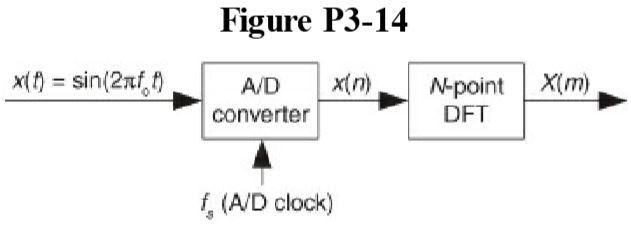

**Answer: **

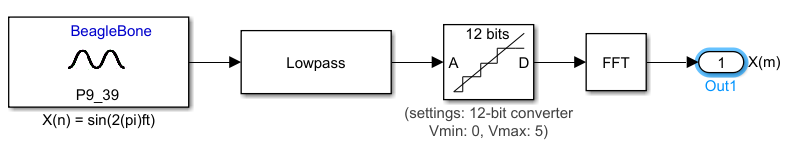

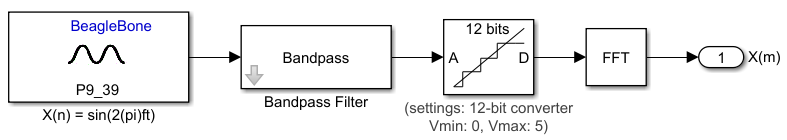

We can use sampling methods shown in chapter 2, such as lowpass filtering and Bandpass filtering.

## **Problem 15:**

**Unable to properly comprehend and execute a procedure to solve the question, would appreciate example done in class**

## **Problem 16:**

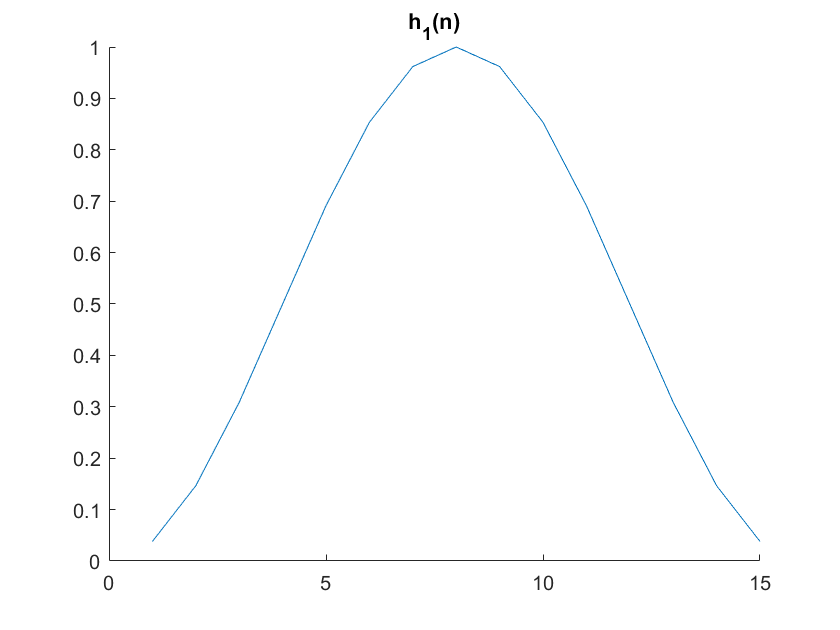

clf
n = 1:47;
figure
for n = 1 : 15
    h1(n) = 0.5-.5*(cos((2*pi*n)/16));
    hold on
    plot(h1)
end
title("h_1(n)")
hold off

**(A) **$h_1 \left(n\right)$ is made of two signals, a DC signal of 0.5, and a signal $-0\ldotp 5\;\mathrm{cos}\left(\frac{2\pi n}{16}\right)$. $h_1 \left(n\right)$ looks the way it does, because it has a positive component of 0.5 meaning the y value is offset by 0.5, and there is a frequency over time that is shifting up and down from 0 to 1 by subtracting the resultant of the signal.

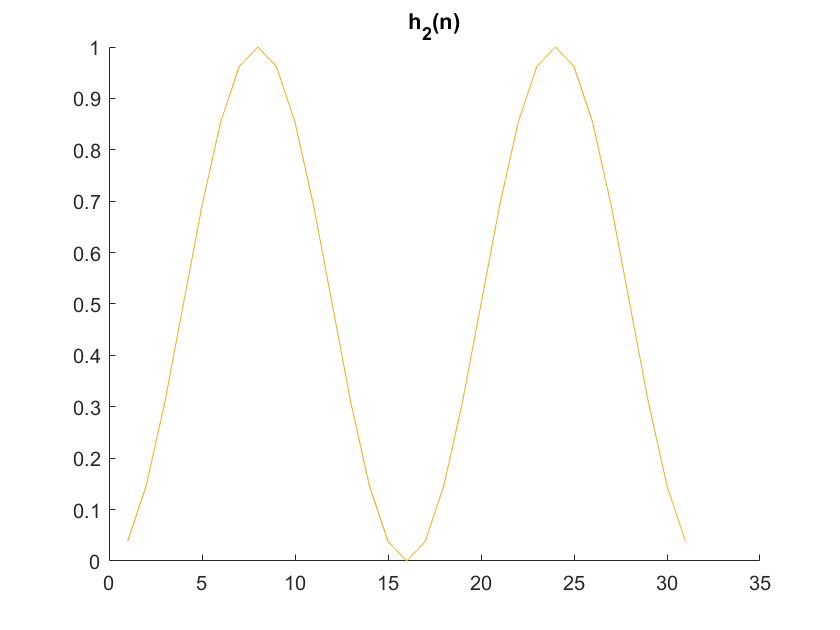

clf
figure
for n = 1 : 31
    h2(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h2)
end
title("h_2(n)")
hold off

**(B)**

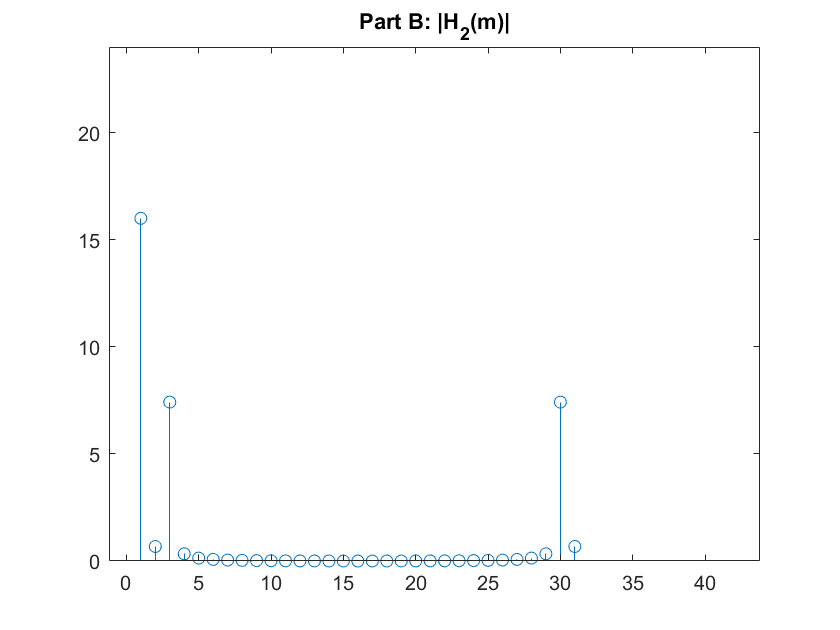

figure
f=abs(real(fft(h2)));
stem(1:31,f)
xlim([-1.2 43.8])
ylim([0.0 24.0])
title("Part B: |H_2(m)|")

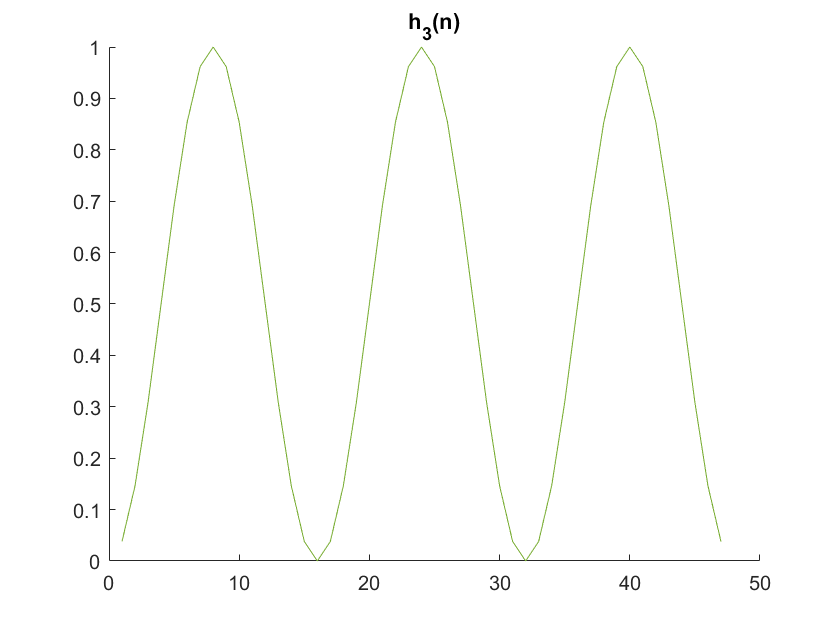

clf
figure
for n = 1 : 47
    h3(n) = .5 -.5*(cos((2*pi*n)/16));
    hold on
    plot(h3)
end
title("h_3(n)")
hold off

**(C)**

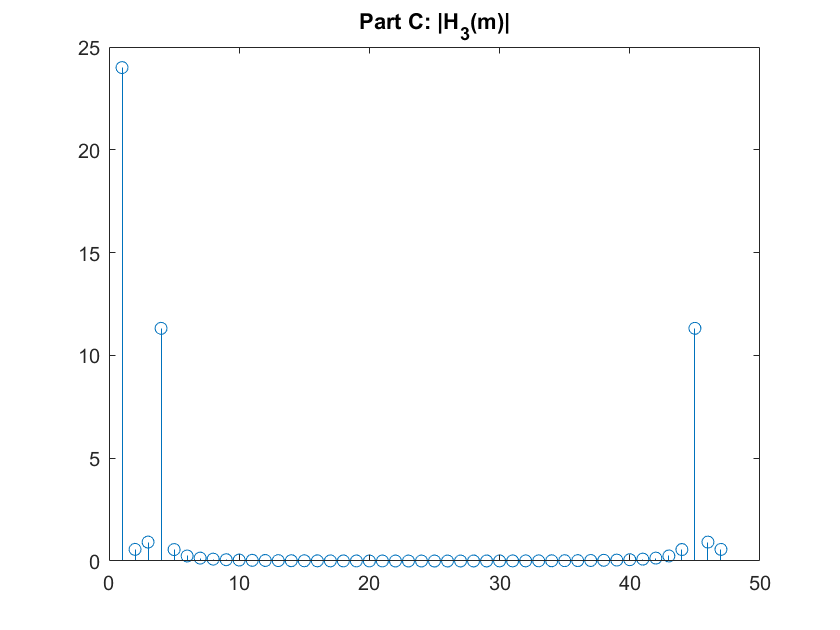

figure
f=abs(real(fft(h3)));
stem(1:47,f)
title("Part C: |H_3(m)|")

**(D)**

**“K repetitions of an h1(n) sequence result in an extended-length time sequence whose spectral magnitudes have K−1 ...”**

**            GAIN**

## **Problem 17:**

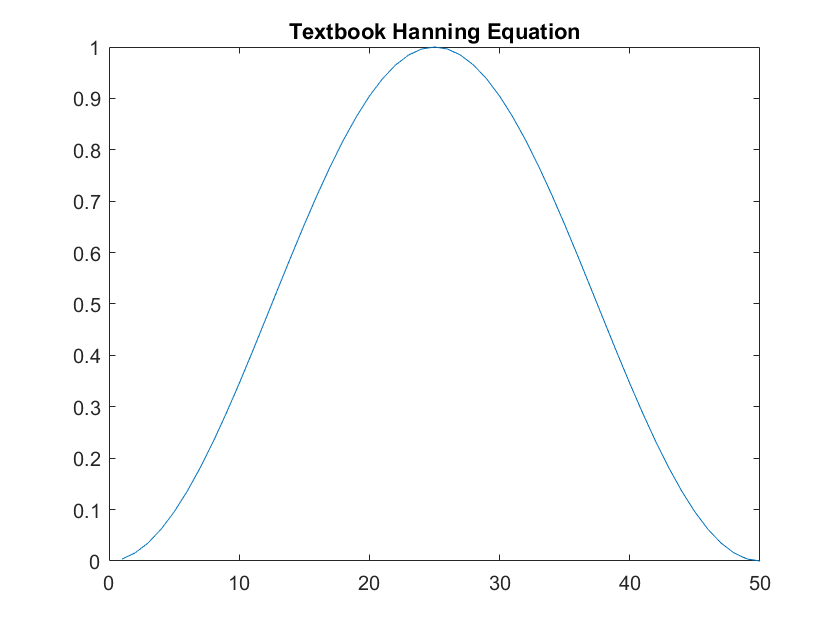

N = 50;
hann1 = zeros(1,N);
hann2 = zeros(1,N);

for n = 1:N
    hann1(n) = 0.5 - 0.5*cos((2*pi*n)/N);
    hann2(n) = sin((pi*n)/N) .^2;
end
figure
plot(hann1)
title('Textbook Hanning Equation')

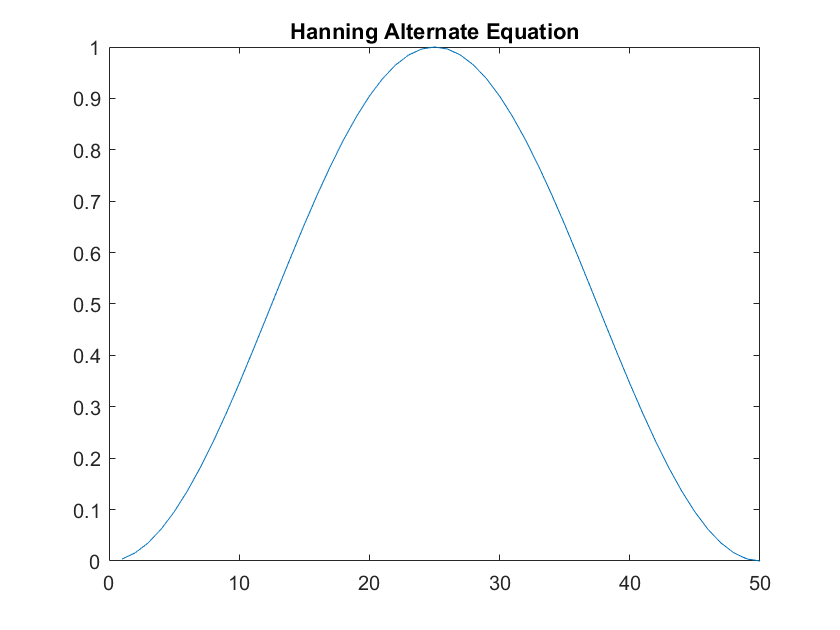

figure
plot(hann2)
title('Hanning Alternate Equation')

## **Problem 18:**

A Continuous fourier transform is performed in which there are a number of padded zeros in the data. The transform creates a centered wave form, where as Q increases the observer will see graphical points that resemble the wave itself.

## **Problem 20:**

SNR_N = 10*log(1000000/100)

SNR_N = 92.1034

Gain of 92.103 in their signal

## Problem 21

**(A)**

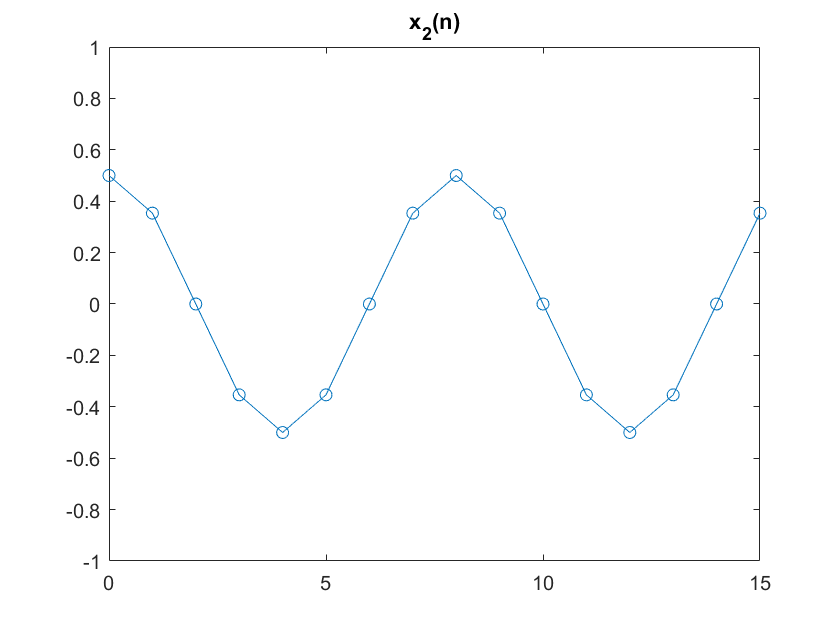

x2 = [0 0 4 0 0 0 0 0 0 0 0 0 0 0 4 0];
t = 0:15;
ycomp = ifft(x2);
yreal = real(ycomp);
plot(t,yreal,'-o')
title 'x_2(n)'
ylim([-1 1]);

**(B)**

This plot looks identical to the original $x_1 \left(n\right)$ sequence, and comparitively looks the same as x(t). It is however dampened and only reaches a range of -0.6 to +0.6.

## Problem 22

There is a useful spectrum analysis process, discussed in Chapter 13, that uses the results of an N-point DFT, X(m), and requires us to compute 

S = P · X(0) − Q · X(N−1) − Q · X(1) 

where P and Q are scalar constants. Value S is the sum of three complex numbers. If we represent the three DFT samples in rectangular form, we can write 

S = P · [a + jb] − Q · [c + jd] − Q · [e + jg]. 

In the general case, the above expression for S requires six real multiply operations. If the DFT’s

x(n) input sequence is real-only, what is the equation for S that requires fewer than six real multiplies? Show your work.

**UNSURE as to what this question pertains to, or is asking, I found information in chapter 13 section 4 about changing from multiplication to addition/subtraction. Although, I failed to find how to accomplish this question.**